# Figure S1D

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A048_data.mat'],'S','settings','allIF');

conditions = settings.conditions;


framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

conds = [29];
figure('units','inches','position',[0 0 4 4]), hold on

POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];


for i=1:length(conds)
    data = S(conds(i));
    inds = ~isnan(S(conds(i)).POI(:,2)) &~isnan(S(conds(i)).POI(:,1));
     mat = NaN * ones(size(data.area));
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 

     hold on
    plot(x,f,'LineWidth',2);
  sum(inds)
  

end

ans = 2062

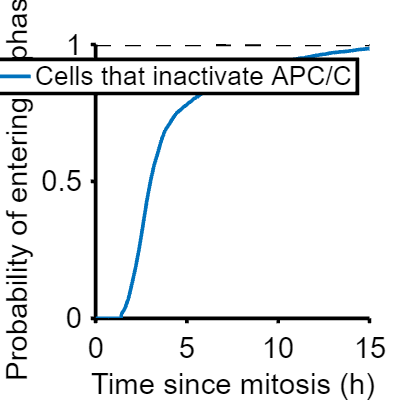

set(gca,'fontsize',16,'linewidth',2)
% legend(conditions(conds,1));
xlim([0 15]); 
hline (1,'k--')
ylim([0 1]);
yticks(0:.5:1)
xlabel('Time since mitosis (h)')
legend ('Cells that inactivate APC/C')
ylabel('Probability of entering S phase')
axis square

% print_pdf(['fig_S1D.pdf'])